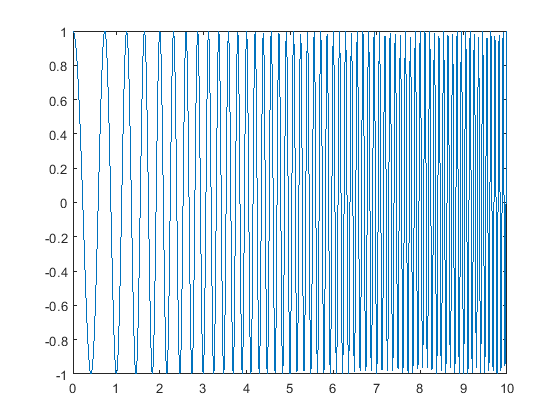

dt = 0.01;
t = 0 : dt : 10;
N = length(t);
gain1 = 1;
gain2 = 1;
startf1 = 1;
startf2 = 1;
time1 = 1;
time2 = 1;
changef1 = 2;
changef2 = 2;
number = 0;
noiseSD = 1;

% chirp signal
y1 = gain1 * chirp(t, startf1, time1, changef1); 
y2 = gain2 * chirp(t, startf2, time2, changef2);

plot(t,y1)

plot(t,y2)

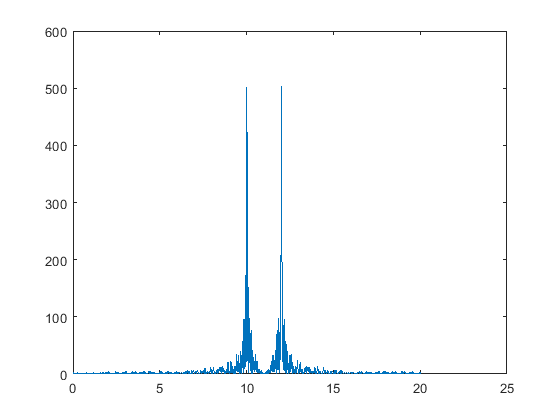

r1 = [ zeros(1,N), y1, zeros(1,N) ];
r2 = [ zeros(1,N+200), y2, zeros(1,N-200) ];
            
r = (r1 + r2) + randn(1,length(r1 + r2))*number*noiseSD;    

% correlation
    ct1 = length(r)-N;
        for a = 0:ct1
            c(a+1) = r(a+1:a+N)*y1';
        end

        plot((0:length(c)-1)*dt,abs(c))

## rectangular

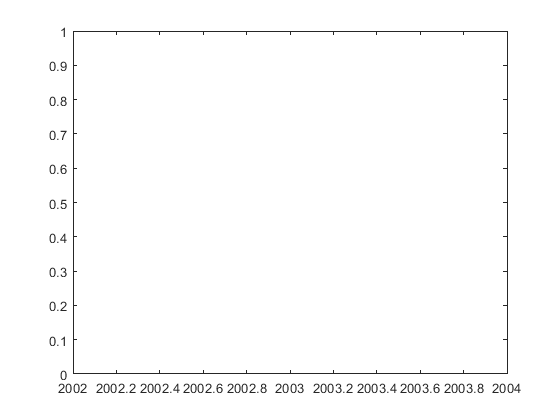

%rectangular

rect1=zeros(1,length(t));
for i=1:length(t) 
    if t(i) > -2 && t(i) < 2
        rect(i) = 1; 
    end
end

rect2=zeros(1,length(r)-N+1);
for i=1:1001 % 배열 인덱스 수 1001개 
    if t(i) > -2000 && t(i) < 2000
        rect2(i) = 1; 
    end
end

plot(length(r)-N+1,rect2)

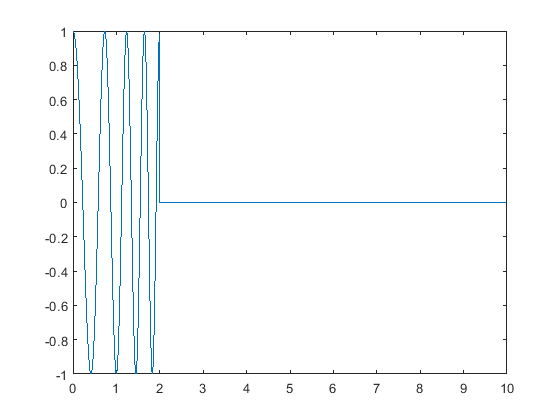


yt1 = y1 .* rect;
yt2 = y2 .* rect;
yt3 = c .* rect2;
plot(t,yt1)

plot(t,yt2)

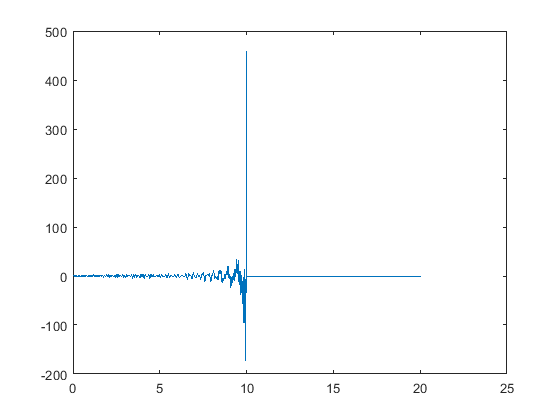

plot((0:length(c)-1)*dt,yt3)


Xt1 = fft(yt1);
Xt2 = fft(yt2);
Xt = Xt1 .* Xt2

Xt = 	1.0e+03 *

   0.0038 + 0.0000i   0.0019 + 0.0081i  -0.0008 + 0.0202i  -0.0001 + 0.0328i  -0.0022 + 0.0405i  -0.0189 + 0.0507i  -0.0535 + 0.0858i  -0.0758 + 0.1786i  -0.0182 + 0.3000i   0.0934 + 0.3651i   0.1732 + 0.4139i   0.2863 + 0.5663i   0.6816 + 0.7840i   1.4874 + 0.6085i   2.0917 - 0.4018i   1.7513 - 1.7068i   0.6963 - 2.5384i  -0.7283 - 2.8481i  -2.6855 - 2.2079i  -3.9456 + 0.6128i  -1.3547 + 3.8252i   2.9231 + 1.9325i   1.3394 - 2.3078i  -2.1031 - 0.3000i   0.7617 + 1.9993i   1.8268 - 1.5836i  -1.8910 - 1.4940i  -0.9126 + 1.6348i   1.0702 + 0.2035i  -0.3135 - 0.4576i   0.1003 + 0.4642i   0.3647 - 0.5041i  -0.6108 - 0.1930i  -0.0229 + 0.4244i   0.1432 - 0.0888i  -0.0637 + 0.0576i   0.1553 - 0.0712i  -0.1716 - 0.1751i  -0.1150 + 0.1527i   0.0696 + 0.0184i  -0.0199 + 0.0050i   0.0639 - 0.0245i  -0.0730 - 0.1017i  -0.0850 + 0.0666i   0.0311 + 0.0258i  -0.0066 - 0.0001i   0.0339 - 0.0149i  -0.0417 - 0.0661i  -0.0617 + 0.0355i   0.0154 + 0.0219i


iXt = ifft(Xt)

iXt =     1.0000    1.9960    2.9799    3.9435    4.8782    5.7757    6.6274    7.4250    8.1602    8.8247    9.4108    9.9110   10.3181   10.6255   10.8271   10.9175   10.8920   10.7466   10.4781   10.0845    9.5643    8.9175    8.1450    7.2487    6.2319    5.0989    3.8553    2.5079    1.0649   -0.4645   -2.0699   -3.7396   -5.4609   -7.2201   -9.0022  -10.7918  -12.5724  -14.3268  -16.0375  -17.6864  -19.2552  -20.7257  -22.0795  -23.2986  -24.3656  -25.2636  -25.9767  -26.4899  -26.7897  -26.8640


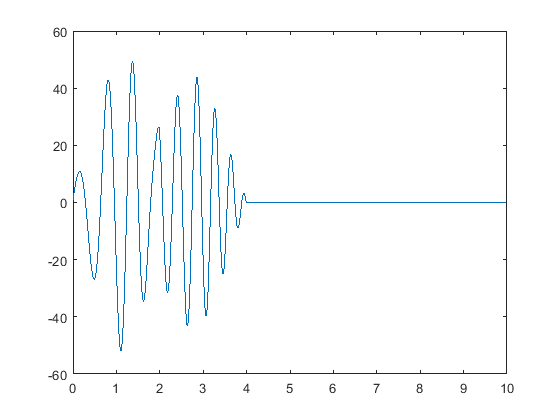

plot(t,iXt)

## hanning

% hanning (0 <= n <= M - 1)
% 1/2 * (1 - cos(2*pi*n/(M-1)))


## hamming

% hamming
% 0.54 - 0.46 * cos(2*pi*n/(M-1))


## blackman

% blackman
% 0.42 - 0.5 * cos(2*pi*n/(M-1)) + 0.08 * cos(4*pi*n/(M-1))


## kaiser

% kaiser
% i0*[ (alpa * sqrt({(M-1)/2)}^2 - {n - (M-1)/2)}^2) ) ]...
% / i0*[(alpa * {(M-1)/2)}^2)]